## Name:

## Date:

## PID: 

# Assignment 5 : Numerical Integration

**General Instructions:** Complete each question to the best of your abilities.  Include comments in your code to explain your thought process while answering.

**Submission Instructions:** Assignment files should be titled Assignment_X_FirstNameLastName, Ex: Assignment_5_AsadMirza. To convert the MLX file into a PDF go to the Export icon under Live Editor and select "Export to PDF".

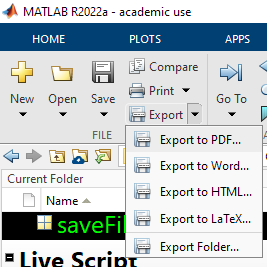

Question 1 (20%): 

A mutated strain of *Cordyceps* fungus has begun producing a strange bioluminescent sheen. Light striking the fungal layer diminishes quickly as spores absorb the energy for metabolic signaling. The amount of light absorbed depends on the material constant, μ, known as the absorption coefficient. 

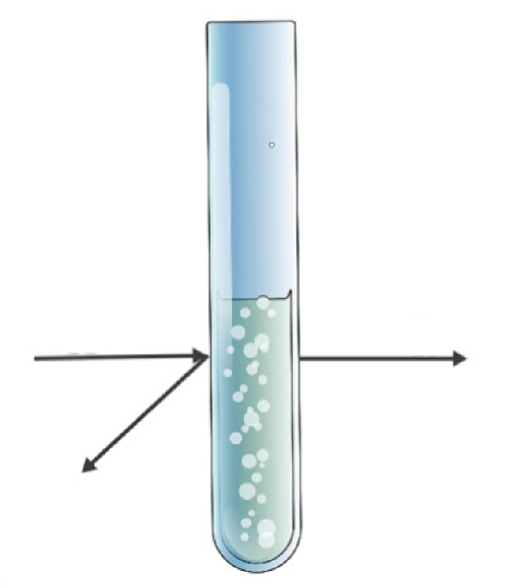

$\frac{dI}{dt}\;\textrm{=}\;\textrm{-}\;\textrm{μ}\textrm{I},\;\;\;I\left(2\right)=1$, $\mu =0\ldotp 35$

a) (10%) Write MATLAB code to approximate the light intensity at $t=4$ seconds for light passing through the fungus from $t=\left\lbrack 2\;\;\;\;\;5\right\rbrack$ seconds using `ode45`.

clear; clc; close all;

t_span = [2 5]

t_span =      2     5


I0 = 1 % I(2) =1

I0 = 1

mu = 0.35

mu = 0.3500



f = @(t, y) -mu * y;

% % Step 3: Apply ODE45
[t, y] = ode45(f, t_span, I0);


% Now for the light intensity at t = 4 part 
fOde = ode45(f, t_span, I0);
I_4 = deval(fOde, 4);
fprintf('Light intensity at t = 4: %.4f\n', I_4);

Light intensity at t = 4: 0.4966


b) (10%) Find the analytical solution using [symbolic math](https://www.mathworks.com/help/symbolic/dsolve.html) or by hand and plot both the MATLAB's ODE solver and the analytical solution, with appropriate axes and legend. 

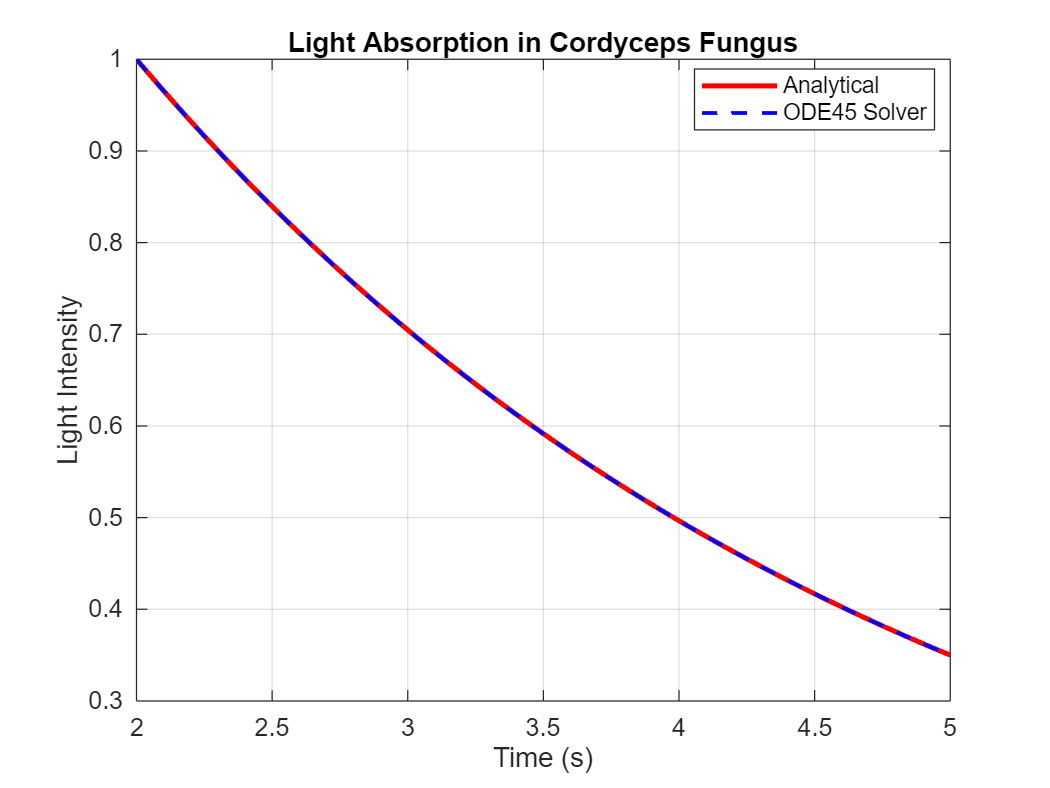

% % Step 1
syms I(t_sym)

eqn = diff(I, t_sym) == -mu * I;

% Initial condition
cond = I(2) == I0;



% % Step 2 
I_sol(t_sym) = dsolve(eqn, cond); % Solve analytically


% % Step 3

figure;
tt = linspace(t_span(1), t_span(2), 100);
plot(tt, I_sol(tt), 'r', 'LineWidth', 2); % analytical solution
hold on;
plot(tt, deval(fOde, tt), '--b', 'LineWidth', 1.5); %ode45
hold off;
xlabel('Time (s)');
ylabel('Light Intensity');
title('Light Absorption in Cordyceps Fungus');
legend('Analytical', 'ODE45 Solver', 'Location', 'Best');
grid on;

Question 2 (20%)

In the infamous city of Raccoon City, population of** 10,000**, a catastrophic leak at the Umbrella Corporation laboratories unleashed the dreaded T-Virus. The viral contamination spread through the streets like wildfire, infecting the first **five** unfortunate citizens, who transformed into grotesque, mindless abominations with an insatiable hunger for human flesh. Panic and chaos erupted overnight, as the city teetered on the brink of total collapse.

Amid the chaos, a brave biomedical engineer infiltrated the quarantined zone, determined to understand the virus. Dodging grasping hands, collapsing buildings, and the relentless growls of the infected, they risked everything to measure the spread and decay parameters of the T-Virus. As the infected closed in, the engineer fell, clutching a bloodstained notebook. With their dying breath, they whispered a desperate plea:

*"You… must… solve… the model… before Raccoon City is lost…"*

From the engineer’s notes, you now know how the populations are expected to change: the human population decreases proportionally to both the number of humans and the infected, while the zombie population grows in proportion to human-to-zombie interactions but decays naturally over time without new hosts. Using the data they risked their life to gather, a bite-induced infection rate of  $0\ldotp 5x\;{10}^{-4}$ per hour and a zombie decay rate of $10\ldotp 3x\;{10}^{-2}$ per hour, you are tasked to predict the rise and fall of the T-Virus outbreak and determine whether any human soul might survive the creeping doom.

a) (5%) Write out the system of differential equations derived from the information above using the Equation Editor underneath the Insert tab. 


$$\begin{array}{l}
\frac{{\mathrm{dP}}_{\mathrm{Humans}} }{\mathrm{dt}}\textrm{=}-c_1 P_{\mathrm{Humans}} P_{\mathrm{Zombies}} \\
\frac{{\mathrm{dP}}_{\mathrm{Zombies}} }{\mathrm{dt}}=c_1 P_{\mathrm{Humans}} P_{\mathrm{Zombies}} -c_2 P_{\mathrm{Zombies}} 
\end{array}$$


b) (10%) Solve the coupled model for the zombie outbreak for the first 100 hours after the zombies appear. Plot the population of humans and zombies on a single graph with appropriate axes and legend.

clear,clc,close all

tspan = [0 100];   % Time interval -- 100 hours
c1 = 0.5e-4; % zombie creation rate
c2 = 10.3e-2;


% Initial populations: [humans, zombies]
y0 = [10000, 5];


predprey = @(t, s) [ ...
    -c1 * s(1) * s(2);    % Rate of decrease of humans due to zombies
     c1*s(1)*s(2) - c2 * s(2)  % Rate of change of zombie population
];

% Set up solver using ode45
[t, s] = ode45(predprey, tspan, y0);

% Plot the results
figure; 
plot(t, s); 
xlabel('Time (hours)');
ylabel('Population (individuals)');
legend('Humans', 'Zombies', 'Location', 'northeast');
title('Human and Zombie Population Dynamics');
grid on;  % Add grid for better readability

c) (5%) Using the model of the T-Virus outbreak in Raccoon City, determine whether there is a time point **after the initial surge of zombies** when the human population once again **surpasses the zombie population**. If such a time exists, report the earliest time when this occurs; otherwise, report the time when humans go extinct.

% s(:,1) = humans, s(:,2) = zombies
% t = time vector

% Set the time after which we start checking
t_start = 40;  % hours

% Find the first time after t_start when humans > zombies
for i = 1:length(t)
    if t(i) > t_start && s(i,1) > s(i,2) % search until human pop > zombie pop
        time_humans_win = t(i); % when surpassd, save as <
        break
    end
end

fprintf('Humans begin outnumbering zombies at %.2f hours.\n', time_humans_win);

Question 3 (20%): 

a) (10%) Write the MATLAB code to compute the given second-order differential equation below, given that $\frac{\textrm{dy}\left(1\right)}{\textrm{dx}}=1$ and  $y\left(1\right)=1$ and x =[1 2].


$$x^2 \frac{d^2 y}{{dx}^2 }+3x\frac{dy}{dx}+y=0$$


clear,clc,close all


b) (10%) Plot the solved system from (a) against the analytical answer, found using either [symbolic math](https://www.mathworks.com/help/symbolic/dsolve.html) or by hand, and provide appropriate axes and legend. 

Question  4 (20%): 

The following is an example of a potentially stiff ODE system:


$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}\textrm{=}-x\\
\frac{\textrm{dy}}{\textrm{dt}}=x-\alpha \;y
\end{array}$$


a) (10%) If $\alpha \;$is 400000, find and plot the solution to the ODE system using [ode45](https://www.mathworks.com/help/matlab/ref/ode45.html) from t = 0 to 1. The initial value of x(0) and y(0) is 1.

clear; clc; close all;


b) (10%) Solve this ODE faster using a different, built-in, MATLAB ODE solver. Quantify how much better it is compared to ode45 from (a). Plot the solution and compare it to your results from (a). Why is this alternative solver, presumably, faster? 

Hint: Use [tic](https://www.mathworks.com/help/matlab/ref/tic.html) [toc](https://www.mathworks.com/help/matlab/ref/toc.html). Comparing solutions is easier if you include markers for data points.

Question 5 (20%)

While exploring a dusty crypt, a team of archaeologists accidentally opened an ancient sarcophagus. To their shock, and mild horror, they found a still-beating heart inside! Most people would have run screaming, but one brave (or slightly reckless) biomedical engineer decided it was the perfect opportunity to model its dynamics instead of re-burying it.

The heart’s electrical activity can be approximated by a forced Van der Pol-like system:


$$\frac{\textrm{dV}}{\textrm{dt}}=W$$



$$\frac{\textrm{dW}}{\textrm{dt}}=\mu \left(1-v^2 \right)W-V+\gamma \sin \left(\omega \;t\right)$$



$$V\left(0\right)=1,W\left(0\right)=0$$


Where:

- $V\left(t\right)=$ voltage of the heart's beat,

- $W\left(t\right)=$ rate of change of voltage,

- $\mu =2$, nonlinearity parameter (how "possessed" the heart is),

- $\gamma =0\ldotp 5$, ghost forcing amplitude,

- $\omega =0\ldotp 4$, frequency of ghostly forcing

If parameter μ ≥ 0, the system will undergo stable oscillations, known as a [limit cycle](https://en.wikipedia.org/wiki/Limit_cycle) whereby the trajectory of the system will form a closed loop.

a) (10%) Solve and plot the Van der Pol ODE system result for a time-span of 100 s. Label axes appropriately and provide a legend.

clear; clc; close all;


b) (5%) Identify the peaks of $V\left(t\right)$ from part (a) to estimate the average heartbeat period and comment on its regularity.

c) (5%) Investigate how increasing the ghostly forcing $\omega$ affects the frequency of $V\left(t\right)$ by plotting and comparing two values of $\omega \;$ 0.4 and 1.